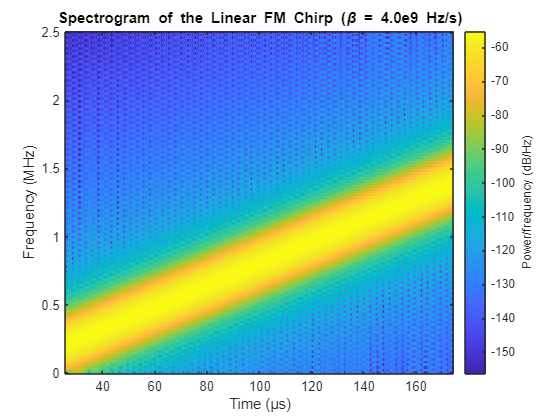

clear; close all; clc;

%% Parameters
fs = 5e6;           % Sampling frequency (5 MHz)
T = 200e-6;         % Duration 200 microseconds
N = T*fs;     % Number of samples
mu = 4.0e9;        % Chirp rate in Hz/s
f0 = 0;              % Initial frequency in Hz

n = 0:N-1;
t = n/fs;

% Generate the chirp signal: x(t) = cos(2*pi*mu*t^2))
x = cos(2*pi*mu*t.^2);

% Spectrogram parameters
win_len = 256;
win = triang(win_len);
overlap = 255;
nfft = 256;

spectrogram(x, win, overlap, nfft, fs, 'yaxis');
title('Spectrogram of the Linear FM Chirp (\beta = 4.0e9 Hz/s)');